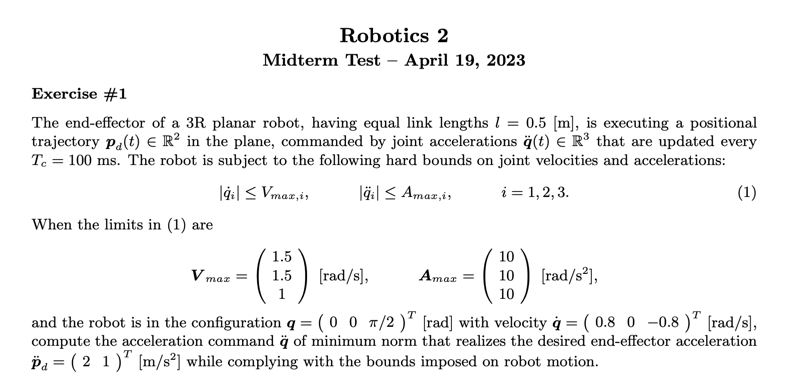

% Definisco le variabili simboliche
syms q1 q2 q3 real
syms qd1 qd2 qd3 real
syms l real

% Abbreviazioni per seno e coseno
c1 = cos(q1);
c12 = cos(q1 + q2);
c123 = cos(q1 + q2 + q3);
s1 = sin(q1);
s12 = sin(q1 + q2);
s123 = sin(q1 + q2 + q3);
 
% Jacobiano
J = l * [
    -s1 - s12 - s123, -s12 - s123, -s123;
    c1 + c12 + c123, c12 + c123, c123
];

% Derivata temporale del Jacobiano (J_dot)
J_dot = sym(zeros(size(J)));
for i = 1:3
    if i == 1
        dJ_dq = diff(J, q1);
    elseif i == 2
        dJ_dq = diff(J, q2);
    else
        dJ_dq = diff(J, q3);
    end
    J_dot = J_dot + dJ_dq * sym(['qd' num2str(i)]);
end

% Calcolo n(q, qd) = J_dot * qd
n = simplify(J_dot * [qd1; qd2; qd3]);

% Valori numerici da sostituire
q1_val = 0;
q2_val = 0;
q3_val = pi/2;
qd1_val = 0.8;
qd2_val = 0;
qd3_val = -0.8;

% Valore di l
l_val = 0.5;

% Substitution dictionary
subs_vars = {q1, q2, q3, qd1, qd2, qd3, l};
subs_vals = {q1_val, q2_val, q3_val, qd1_val, qd2_val, qd3_val, l_val};

% Sostituzioni in J, J_dot e n
J_numeric = simplify(subs(J, subs_vars, subs_vals));
J_dot_numeric = simplify(subs(J_dot, subs_vars, subs_vals));
n_numeric = simplify(subs(n, subs_vars, subs_vals));

% Output
disp('Matrice Jacobiana J con valori sostituiti:')

Matrice Jacobiana J con valori sostituiti:


disp(J_numeric)

$$\left(\begin{array}{ccc} -\frac{1}{2} & -\frac{1}{2} & -\frac{1}{2}\\ 1 & \frac{1}{2} & 0 \end{array}\right)$$


disp('Derivata temporale Jacobiana J_dot con valori sostituiti:')

Derivata temporale Jacobiana J_dot con valori sostituiti:


disp(J_dot_numeric)

$$\left(\begin{array}{ccc} -\frac{4}{5} & -\frac{2}{5} & 0\\ 0 & 0 & 0 \end{array}\right)$$


disp('Vettore n(q, qd) con valori sostituiti:')

Vettore n(q, qd) con valori sostituiti:


disp(n_numeric)

$$\left(\begin{array}{c} -\frac{16}{25}\\ 0 \end{array}\right)$$


% Conversione in numerico (double)
disp('Matrice Jacobiana J valutata numericamente:')

Matrice Jacobiana J valutata numericamente:


disp(double(J_numeric))

   -0.5000   -0.5000   -0.5000
    1.0000    0.5000         0




disp('J_dot valutata numericamente:')

J_dot valutata numericamente:


disp(double(J_dot_numeric))

   -0.8000   -0.4000         0
         0         0         0




disp('n valutata numericamente:')

n valutata numericamente:


disp(double(n_numeric))

   -0.6400
         0

